%Wednesday 4th May, 2022d VERSION 1
%Monday 06/06/2022 VERSION 2

%Link-budget program for any wavelength.

%AUTHORS: Cecilia Arrizabalaga Díaz-Caneja
%         Jorge Lorenzo Álvarez
%         (ULL Physics students-Externship)
%         Joan Torras 
%         Jorge Socas 
%         (Free Space Optics Communications Department at IAC)

%DESCRIPTION: This is a program that calculates the total losses and link margin in an optical satellite-to-ground communication link.
%             There are needed the "Losses_Gains_LB_s2g.mlx" from folder
%             "Losses" and "Parameters_LB_s2g.mlx" from folder "Parameters".

clc;        % clean the command console
clearvars;  % clean all variables in the workspace. Use 'clear all' for older versions of MATLAB
close all;  % close all open figures, windows, etc.

fprintf("Thank you for using our program")

Thank you for using our program

fprintf("This following calculations are only valid for:")

This following calculations are only valid for:

fprintf("UPLINK: Ground to Satellite")

UPLINK: Ground to Satellite

fprintf("DOWNLINK: Satellite to Ground")

DOWNLINK: Satellite to Ground

fprintf("HORIZONTAL: Link between two points in earth")

HORIZONTAL: Link between two points in earth

load MODTRAN.dat
dir = input("Specify link direction: (U = uplink / D = downlink)", "s");
if strcmp(dir,"U")
    %Needed parameters are imported
    run(pwd+"/LB_JC/Parameters/Parameters_LB_s2g.mlx")
    %Calculated losses ardownlink
    % e imported
    run(pwd+"/LB_JC/Losses/Losses_Gains_LB_s2g.mlx")
    L_total = G_trans_dB + G_rec_dB + L_point_dB + L_sci_dB + fiber_loss + L_fs_dB + L_a_dB + L_rcp_dB - 2.33; %The -2.33dB comes from the difference in the turbulence losses for uplink and downlink connections.
elseif strcmp(dir,"D")
    %Needed parameters are imported
    run(pwd+"/LB_JC/Parameters/Parameters_LB_s2g.mlx")
    %Calculated losses are imported
    run(pwd+"/LB_JC/Losses/Losses_Gains_LB_s2g.mlx")
    L_total = G_trans_dB + G_rec_dB + L_point_dB + L_sci_dB + fiber_loss + L_fs_dB + L_a_dB + L_rcp_dB;
else
    fprintf("Please get a hold of yourself :).")
end

Write down the nominal turbulence at ground level:1 - A0 = 1.7*10^(-14)2 - A0 = 1.7*10^(-13)


p_t_W = input("Transmit power (W):");
p_t = 10*log10(p_t_W);
s_d = input("Detector sensitivity (dBm):");
x_dBw = L_total + p_t;   
p_r = x_dBw + 30  ;           
L_MARGIN = p_r-s_d ;     %Link Margin

disp=fprintf("LINK BUDGET CALCULATOR FREE SPACE OPTICAL CHANNEL \n");

LINK BUDGET CALCULATOR FREE SPACE OPTICAL CHANNEL 


disp=fprintf("Pr = Pt + Gr + Gt + Lfsl + La + Lpt + Lsci \n");

Pr = Pt + Gr + Gt + Lfsl + La + Lpt + Lsci 


disp=fprintf("OGS AND SATELLITE MODELING \n");

OGS AND SATELLITE MODELING 


disp=fprintf("Wavelegth selected: %.5f nm \n", wave_length);

Wavelegth selected: 1550.00000 nm 


disp=fprintf("GROUND STATION \n");

GROUND STATION 


disp=fprintf("Telescope Aperture:  %.5f cm \n", D_trans);

Telescope Aperture:  50.00000 cm 


disp=fprintf("Altitude of the Ground Station: %.5f Km \n", H_ground);

Altitude of the Ground Station: 2.30000 Km 


disp=fprintf("Angle of elevation: %.5f degrees \n", theta);

Angle of elevation: 53.00000 degrees 


disp=fprintf("SATELLITE \n");

SATELLITE 


disp=fprintf("Telescope Aperture:  %.5f cm \n", D_rec);

Telescope Aperture:  180.00000 cm 


disp=fprintf("Altitude of the satellite (With NADIR):  %.5f Km \n", H_sat);

Altitude of the satellite (With NADIR):  36000.00000 Km 


disp=fprintf("Altitude of the satellite (With OGS position):  %.5f Km \n", d_link);
disp=fprintf("FSO CHANNEL MODELING \n");

FSO CHANNEL MODELING 


disp=fprintf("Real distance between OGS-Sat : %.5f km \n", d_link);

Real distance between OGS-Sat : 37110.11477 km 


disp=fprintf("Elevation angle : %.5f º \n", theta);

Elevation angle : 53.00000 º 


disp=fprintf("FREE SPACE LOSS Lfsl : %.5f dB \n", L_fs_dB);

FREE SPACE LOSS Lfsl : -289.56741 dB 


disp=fprintf("GAINS TX Telescope : %.5f dB \n", G_trans_dB);

GAINS TX Telescope : 120.11576 dB 


disp=fprintf("GAINS RX Telescope : %.5f dB \n", G_rec_dB);

GAINS RX Telescope : 131.24181 dB 


disp=fprintf("ATMOSPHERIC ATTENUATION (ABSORTION) : %.5f dB \n", L_a_dB);

ATMOSPHERIC ATTENUATION (ABSORTION) : 0.63952 dB 


disp=fprintf("Transmittance in wavelength selected : %.5f \n", L_zen);

Transmittance in wavelength selected : 0.92534 


disp=fprintf("POINTING ERROR LOSS (Lpt) : %.5f dB \n", L_point_dB);

POINTING ERROR LOSS (Lpt) : -0.46994 dB 


disp=fprintf("SCINTILLATION LOSS (Lsc) : %.5f dB \n", L_sci_dB);

SCINTILLATION LOSS (Lsc) : -0.03455 dB 


disp=fprintf("Rytov Index : %.5f \n", sigp_2);

Rytov Index : 0.00634 


disp=fprintf("Scintillation Index without AA : %.5f \n", sigI_point_2);

Scintillation Index without AA : 0.00635 


disp=fprintf("Aperture Averaging (AA) : %.5f \n", A_Dr);

Aperture Averaging (AA) : 0.00604 


disp=fprintf("Scintillation Index c/AA : %.5f \n", sigI_2);

Scintillation Index c/AA : 0.00004 


disp=fprintf("COUPLING FIBER LOSS : %.5f \n", fiber_loss);

COUPLING FIBER LOSS : -3.00000 


disp=fprintf("TOTAL LOSSES : %.5f dB \n",L_total);

TOTAL LOSSES : -43.78720 dB 


disp=fprintf("Link Availability : %.5f % del tiempo \n",p0);

Link Availability : 90.00000 

disp=fprintf("power TX :%.5f dBW \n",p_t);

power TX :0.00000 dBW 


disp=fprintf("Power TX :%.5f dBm \n",p_t+30);

Power TX :30.00000 dBm 


disp=fprintf("The received power is: %.5f dBm \n", p_r);

The received power is: -13.78720 dBm 


disp=fprintf("The sensibility in Rx is: %.5f dBm \n", s_d);

The sensibility in Rx is: -40.00000 dBm 



if L_MARGIN >= 0 
    disp=fprintf("LINK MARGIN: %.5f dB \n",L_MARGIN);
else
    disp=fprintf("No Margin \n")
end

LINK MARGIN: 26.21280 dB 


disp=fprintf("Other Losses not include: \n");

Other Losses not include: 


disp=fprintf("Visibility: %.5f km \n",Visibility);

Visibility: 120.00000 km 


disp=fprintf("Effect of Rain: %.5f dB/km \n",Beta_lluvia);

Effect of Rain: 0.02333 dB/km 


disp=fprintf("Effect of fog: %.5f dB/km \n",Beta_niebla);

Effect of fog: 0.00001 dB/km 


disp=fprintf("Effect of snow : %.5f dB/km \n",Beta_nieve);

Effect of snow : 0.48333 dB/km 


fprintf("Graph MODTRAN file");

Graph MODTRAN file

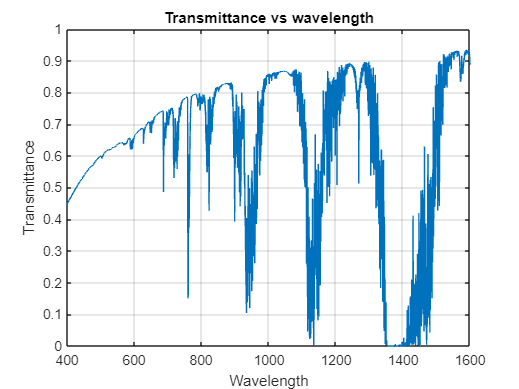

% Ploteamos la grafica dada por MODTRAN
plot (MODTRAN(:,1),MODTRAN(:,2))
title ('Transmittance vs wavelength');
xlabel('Wavelength');
ylabel('Transmittance');
grid on

fprintf("Graph Cn2 Apply");

Graph Cn2 Apply

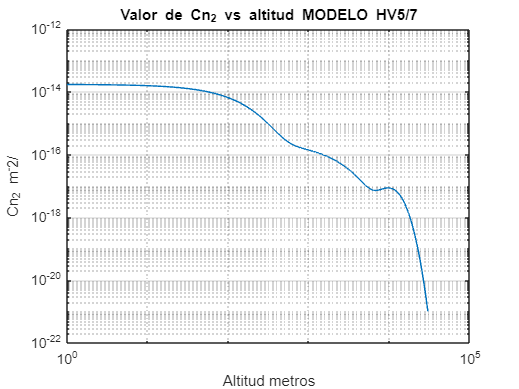

%Ploteamos el resultado Grafica HV5/7
loglog(h,Cn2)
title('Valor de Cn_2 vs altitud MODELO HV5/7')
xlabel ('Altitud metros')
ylabel ('Cn_2 m^-2/')
grid on

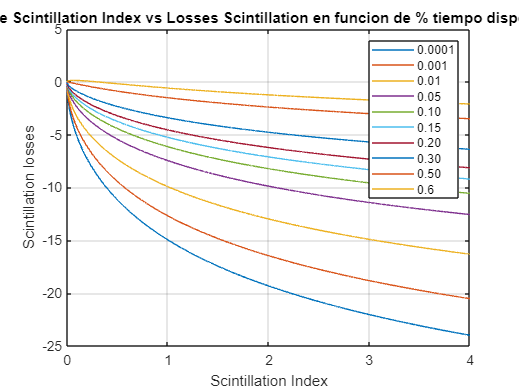

%Ploteamos el valor de Atenuacion por centelleo Vs indice de centelleo
plot (Power_Scintillation,L_sci_dB_graph);
title('Valor de Scintillation Index vs Losses Scintillation en funcion de % tiempo disponibilidad');
xlabel ('Scintillation Index');
ylabel ('Scintillation losses');
grid on;
legend ('0.0001','0.001','0.01','0.05','0.10','0.15','0.20','0.30','0.50','0.6');

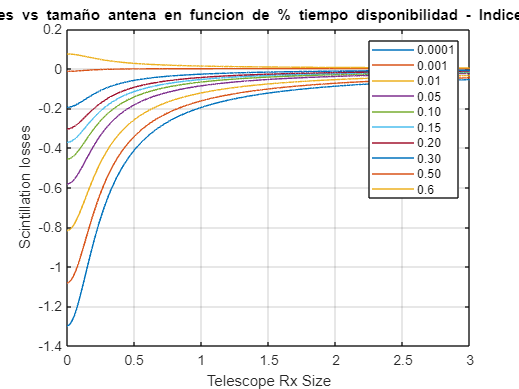

%Ploteamos como varia la Att con el tamaño de la antena para diferentes %
%de disponibilidad
plot (tamano_antena,L_sci_dB_graph2)
title('Valor de Scintillation Losses vs tamaño antena en funcion de % tiempo disponibilidad - Indice de centelleo Fijo (sigI_point_2)');
xlabel ('Telescope Rx Size');
ylabel ('Scintillation losses');
grid on;
legend ('0.0001','0.001','0.01','0.05','0.10','0.15','0.20','0.30','0.50','0.6');